meanSpeedAllTrials_eachSess = [];

clear n
for n = 1:nGroup
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthMeanSpeedAllTrials = groupMeanSpeedAllTrials{1,n};
    meanSpeedAllTrials_eachSess = [meanSpeedAllTrials_eachSess,nthMeanSpeedAllTrials];
    
end 

% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials_eachSess] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials_eachSess,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1662


sizeMeanSpeedAllTrials =            1        1662


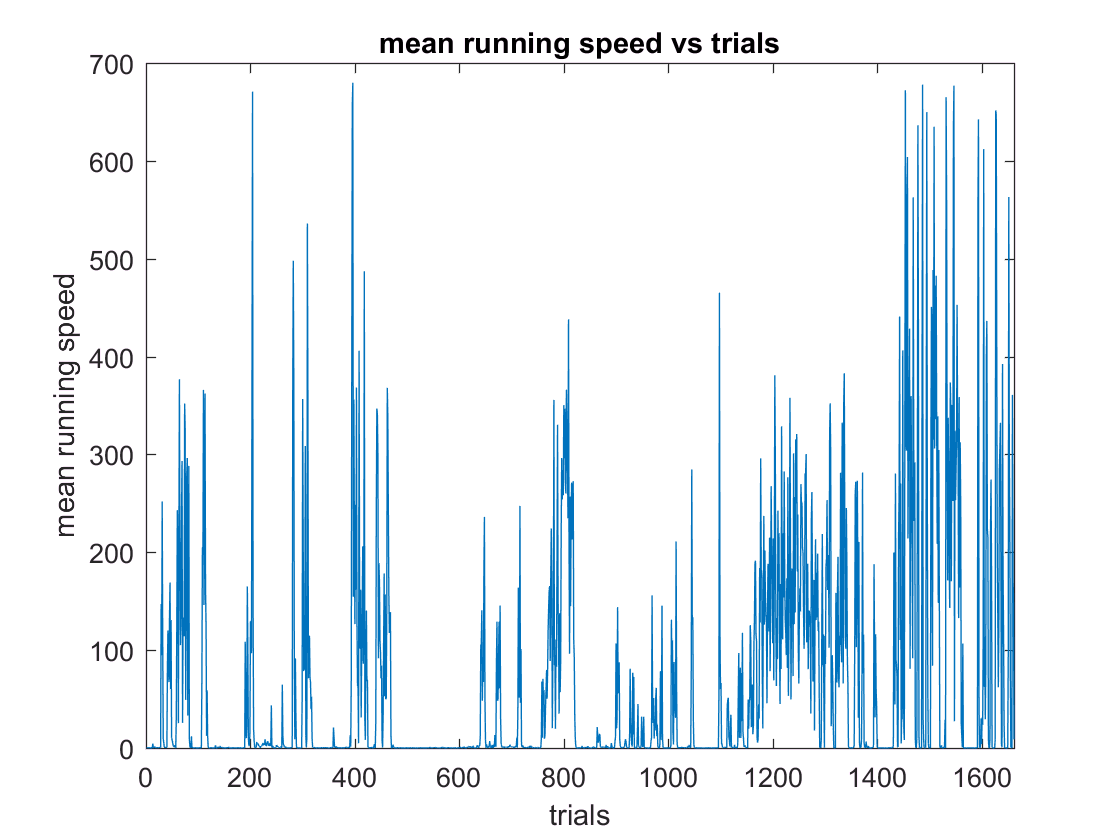

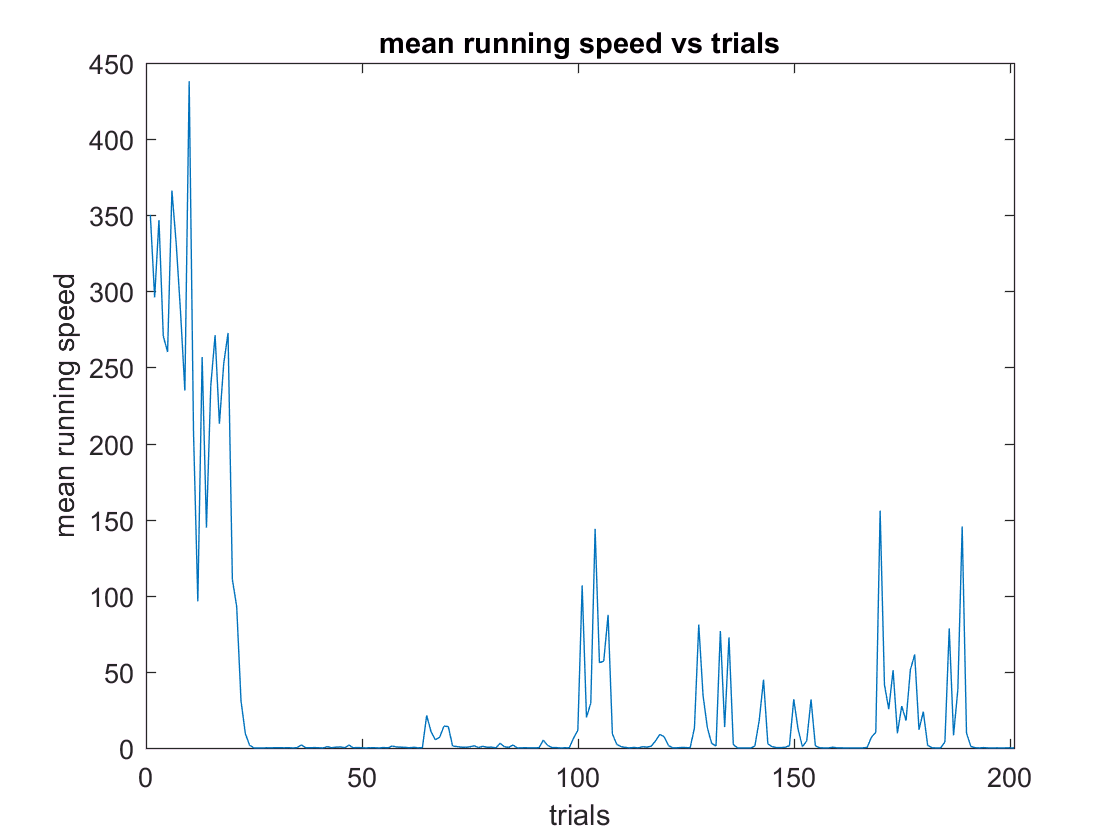

sizeMeanSpeedAllTrials = size(meanSpeedAllTrials_eachSess)

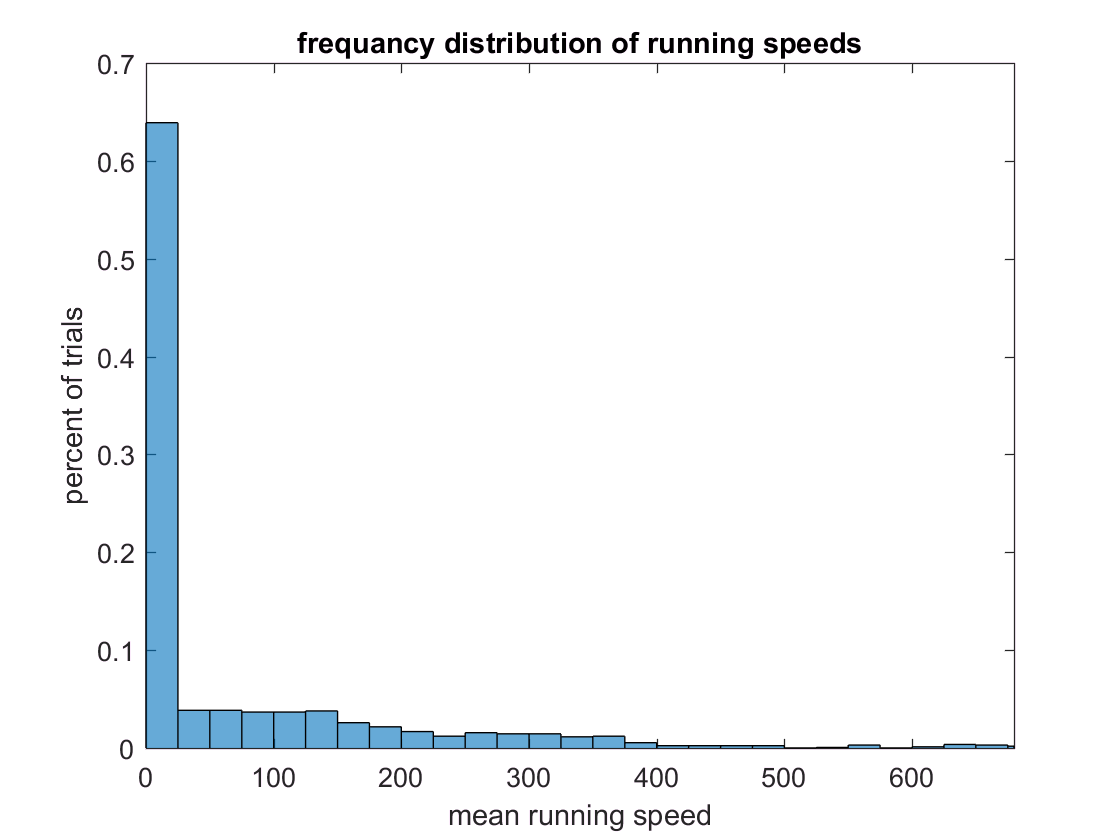


% HISTOs

%Bin edges, specified as a vector. edges(1) is the left edge of the first bin, 
%and edges(end) is the right edge of the last bin.
edges = [0 0:25:max(meanSpeedAllTrials_eachSess) max(meanSpeedAllTrials_eachSess)];
histogram(meanSpeedAllTrials_eachSess,edges,'normalization','probability')
xlim([0 max(meanSpeedAllTrials_eachSess)])
ylabel('percent of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds')


% alternately, use bins
%numTrials = length(meanSpeedAllTrials)
numBins = 10

numBins =     10


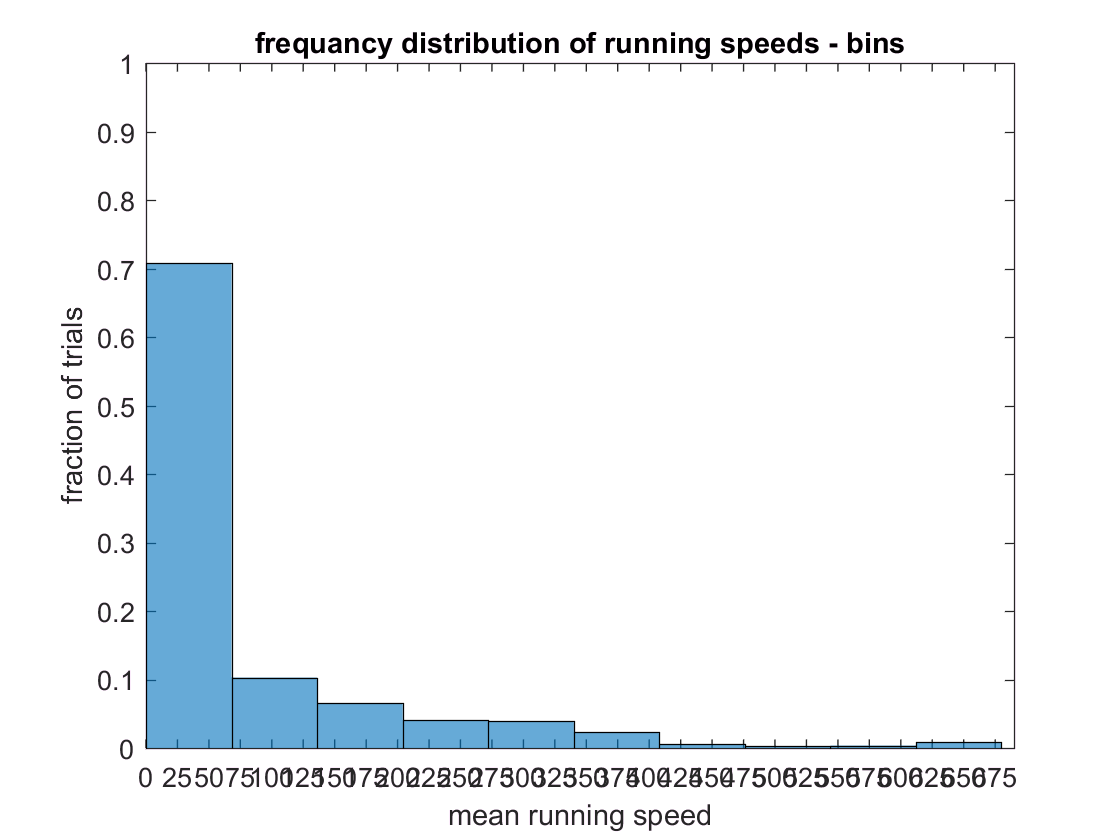

numTrials =         1662


numBins =     10


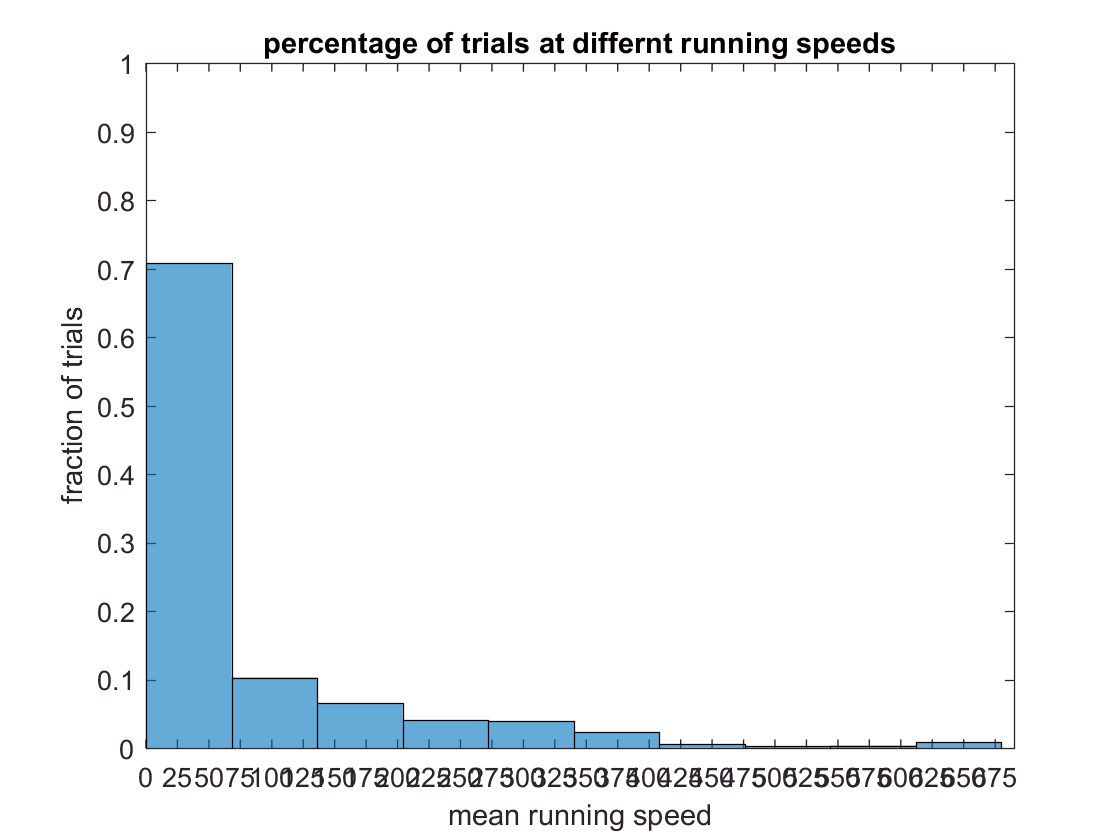

histogram(meanSpeedAllTrials_eachSess,numBins,'normalization','probability')
ylabel('fraction of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds - bins')
xlim([0 round(max(meanSpeedAllTrials_eachSess)+10)])
set(gca,'xtick',0:25:round(max(meanSpeedAllTrials_eachSess)+10));
ylim([0 1])


% PUPIL

meanPupDiameterAllTrials_eachSesss = [];

clear n
for n = 1:nGroup
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthMeanPupDiameterAllTrials = groupMeanPupilDiameterAllTrials{1,n};
    meanPupDiameterAllTrials_eachSesss = [meanPupDiameterAllTrials_eachSesss,nthMeanPupDiameterAllTrials];
    
end 

% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanPupDiameterAllTrials_eachSesss] = filterOnsets_removeEarlyAndLateTrials(meanPupDiameterAllTrials_eachSesss,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1662


sizemeanSpeedAllTrials = size(meanPupDiameterAllTrials_eachSesss)

sizemeanSpeedAllTrials =            1        1662



% HISTO
edges = [0 0:1:max(meanPupDiameterAllTrials_eachSesss) max(meanPupDiameterAllTrials_eachSesss)];
h = histogram(meanPupDiameterAllTrials_eachSesss,edges,'Normalization','probability')

h =   Histogram with properties:

             Data: [1x1662 double]
           Values: [1x53 double]
          NumBins: 53
         BinEdges: [0 0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 51.096]
         BinWidth: 'nonuniform'
        BinLimits: [0 51.096]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


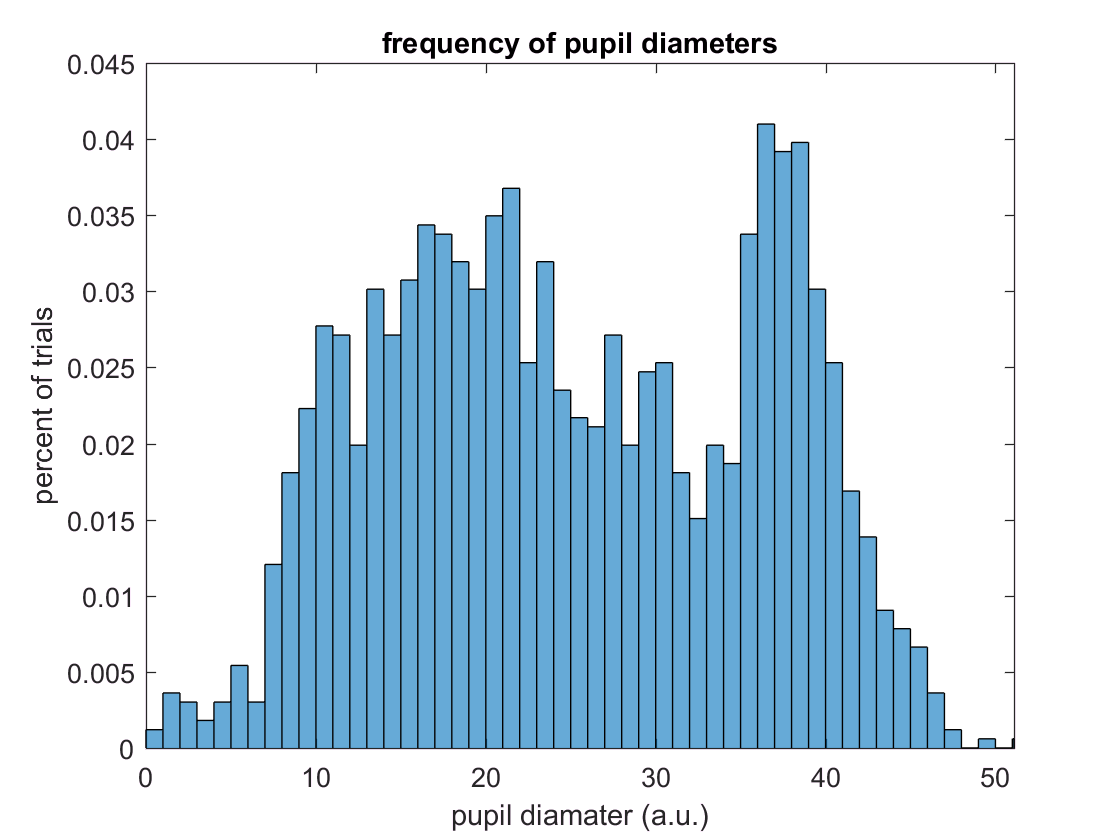

xlim([0 max(meanPupDiameterAllTrials_eachSesss)])
title('frequency of pupil diameters')
xlabel('pupil diamater (a.u.)')
ylabel('percent of trials')

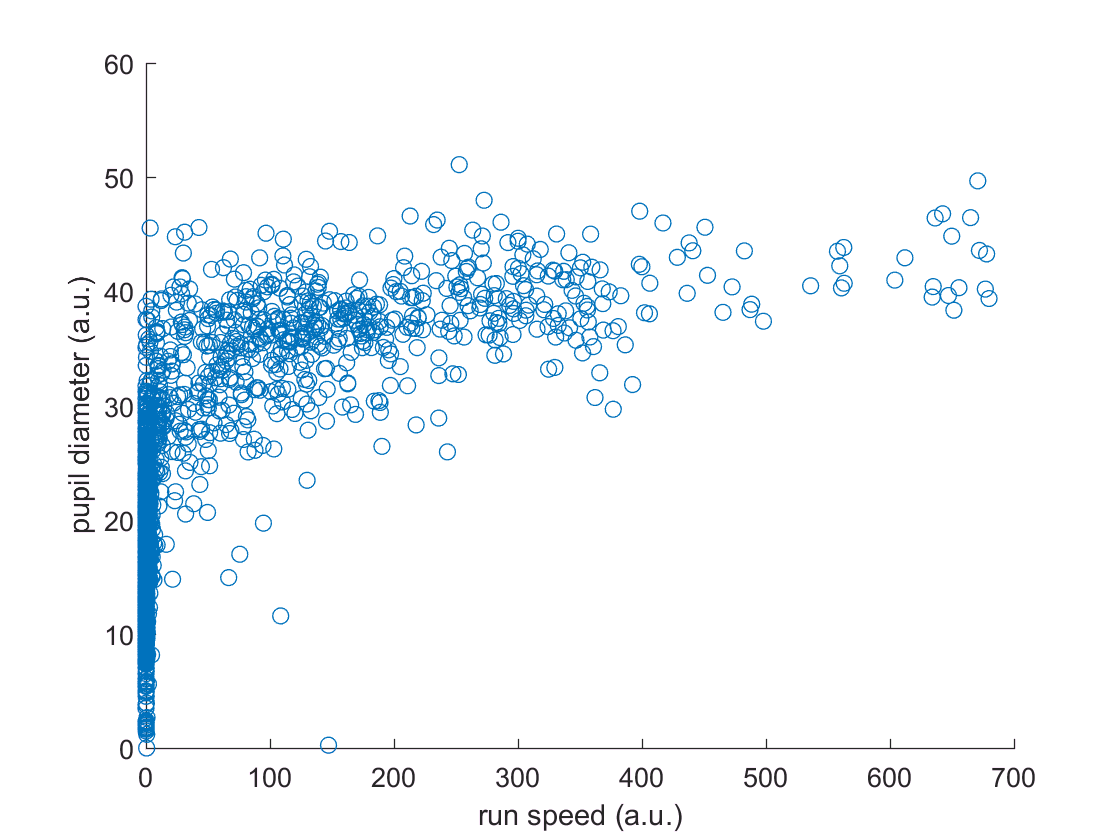


figure
scatter(meanSpeedAllTrials_eachSess,meanPupDiameterAllTrials_eachSesss)
xlabel('run speed (a.u.)')
ylabel('pupil diameter (a.u.)')